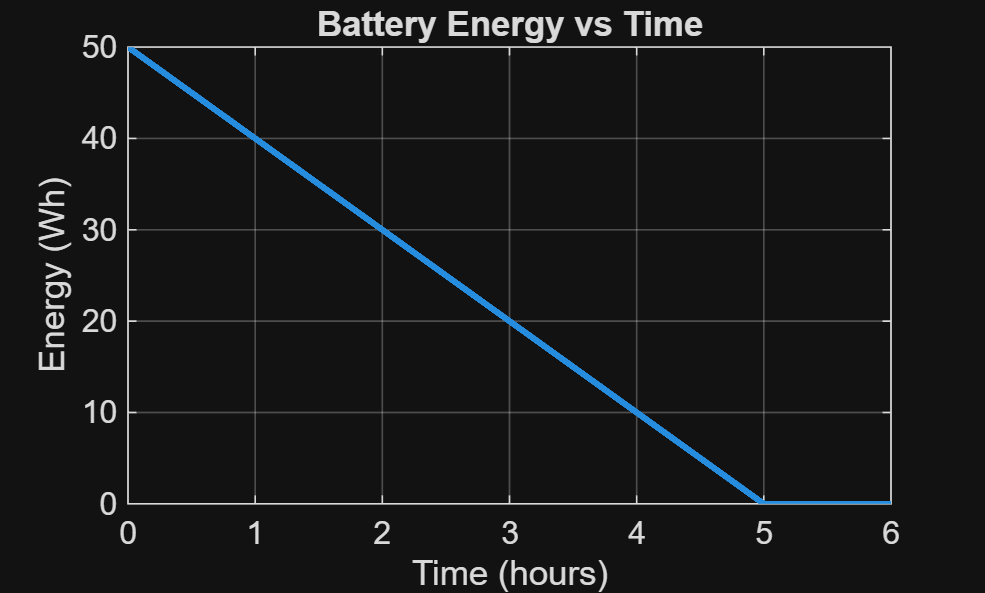

clc;
clear;
close all;

% Parameters
E0 = 50;          % Initial energy (Wh)
P = 10;           % Constant load power (W)
dt = 1;           % Time step (s)
t_end = 6*3600;   % Simulation duration (s)

% Time vector
t = 0:dt:t_end;

% Convert power consumption to Wh per second
P_wh = P / 3600;

% Initialize energy vector
E = zeros(size(t));
E(1) = E0;

% Energy depletion loop
for i = 2:length(t)
    E(i) = E(i-1) - P_wh*dt;

    if E(i) < 0
        E(i) = 0;
    end
end

% Approximate voltage decay
V0 = 12;
V = V0 * (E/E0);

% Plot energy
figure;
plot(t/3600, E, 'LineWidth', 2);
xlabel('Time (hours)');
ylabel('Energy (Wh)');
title('Battery Energy vs Time');
grid on;

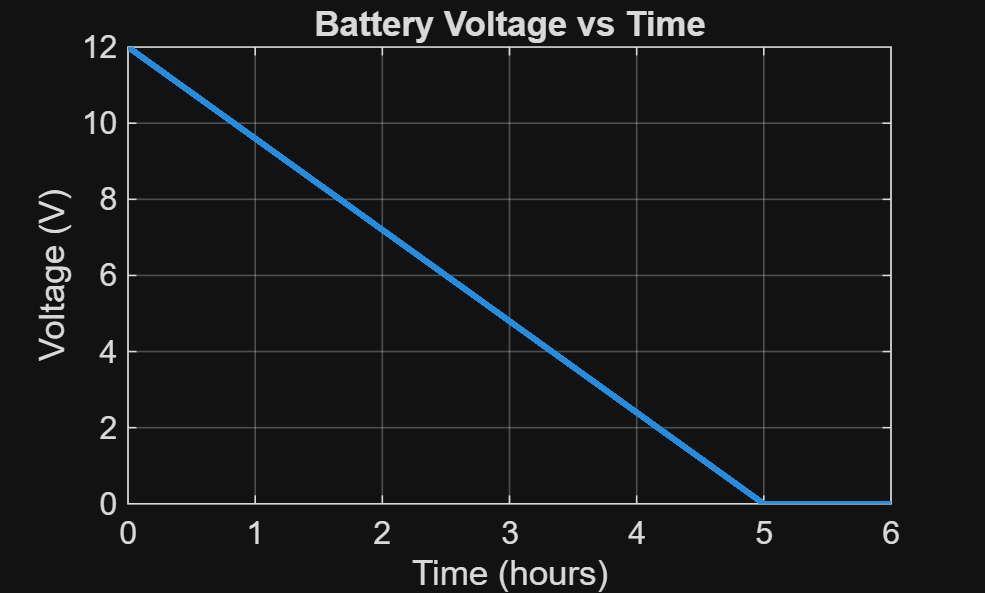


% Plot voltage
figure;
plot(t/3600, V, 'LineWidth', 2);
xlabel('Time (hours)');
ylabel('Voltage (V)');
title('Battery Voltage vs Time');
grid on;

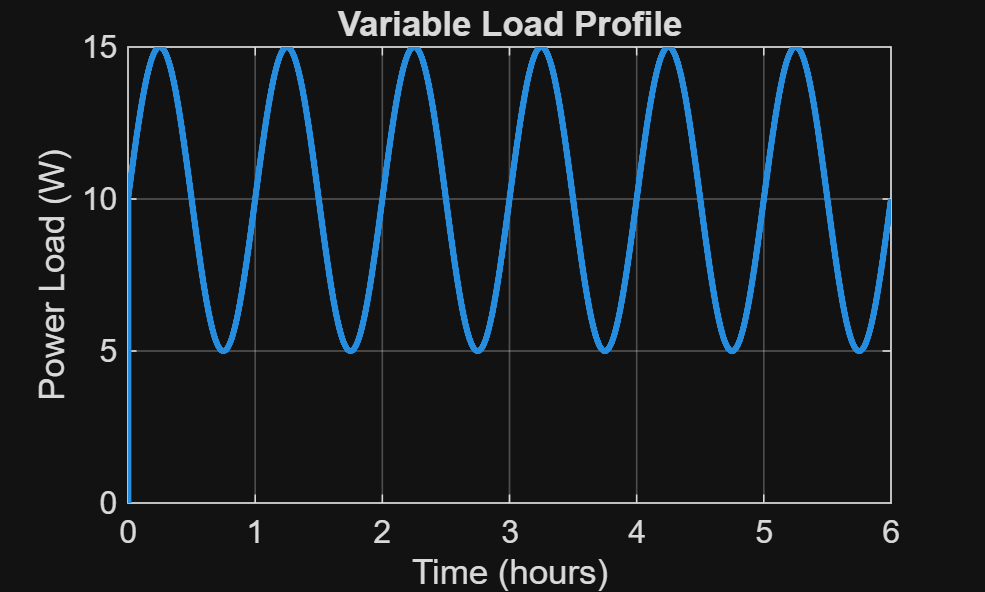

clc;
clear;
close all;

% Parameters
E0 = 50;          % Initial energy (Wh)
dt = 1;           % Time step (s)
t_end = 6*3600;

% Time vector
t = 0:dt:t_end;

% Initialize vectors
E = zeros(size(t));
P = zeros(size(t));

E(1) = E0;

for i = 2:length(t)

    % Variable load
    P(i) = 10 + 5*sin(2*pi*t(i)/3600);

    % Convert W to Wh/s
    P_wh = P(i)/3600;

    % Update battery energy
    E(i) = E(i-1) - P_wh*dt;

    if E(i) < 0
        E(i) = 0;
    end
end

% Voltage approximation
V0 = 12;
V = V0*(E/E0);

% Plot load profile
figure;
plot(t/3600, P, 'LineWidth', 2);
xlabel('Time (hours)');
ylabel('Power Load (W)');
title('Variable Load Profile');
grid on;

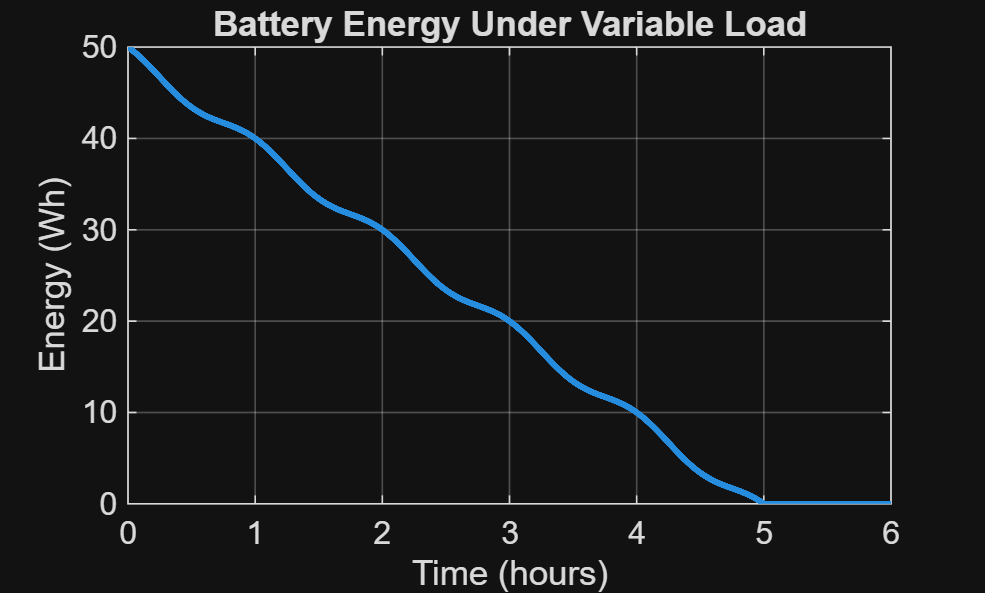


% Plot energy
figure;
plot(t/3600, E, 'LineWidth', 2);
xlabel('Time (hours)');
ylabel('Energy (Wh)');
title('Battery Energy Under Variable Load');
grid on;

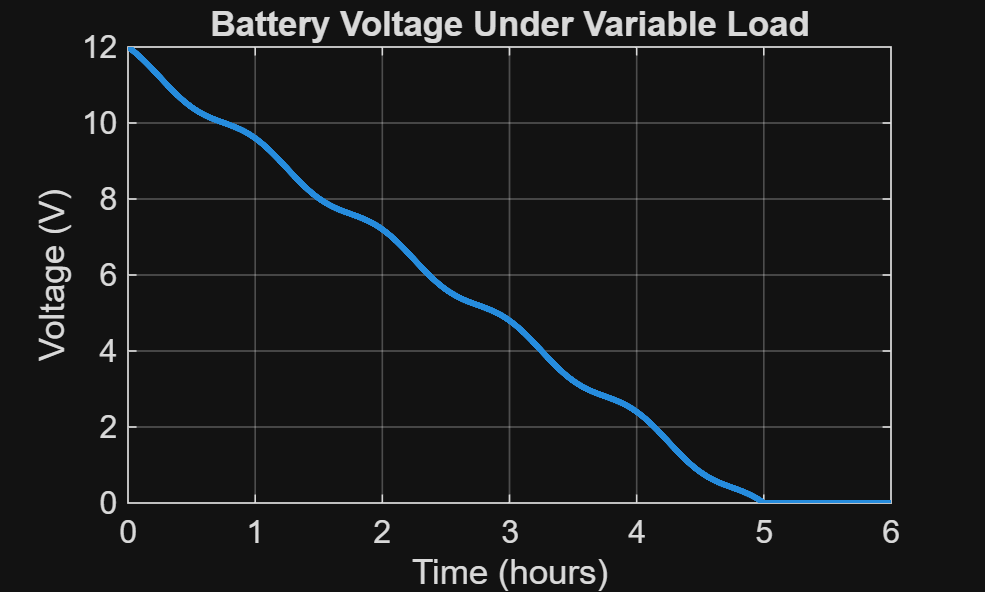


% Plot voltage
figure;
plot(t/3600, V, 'LineWidth', 2);
xlabel('Time (hours)');
ylabel('Voltage (V)');
title('Battery Voltage Under Variable Load');
grid on;